format short
u = symunit;
SIUnits = baseUnits('SI');
% separateUnits(x)
% unitConvert(expr, target)

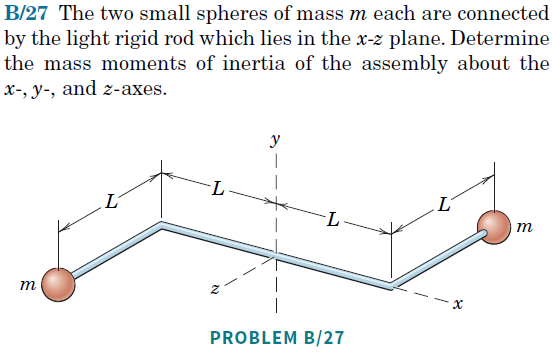

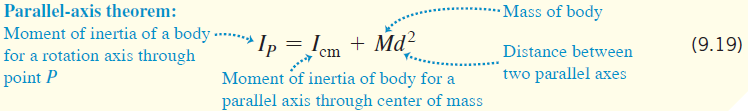

Vi har 5 elementer 3 stænger og 2 kugler

stængerne går ud og bliver 0 da massen ses som 0

kuglerne har ingen radius sp kun forskydningen giver bidrag

syms L M_k
M_s = 0

M_s = 0

%Første stang går igennem axen
stang1_I_xx = M_s * (2*L)^2 / 12

$$stang1\_I\_xx = 0$$

stang1_I_yy = M_s * (2*L)^2 / 12

$$stang1\_I\_yy = 0$$

stang1_I_zz = M_s * (2*L)^2 / 12

$$stang1\_I\_zz = 0$$


%de to andre stænger går ikke igennen centrum og skal forskydes
stang2_I_xx = M_s * L^2 / 12 + M_s * L^2

$$stang2\_I\_xx = 0$$


stang2_I_yy = M_s * L^2 / 12 + M_s * sqrt((L/2)^2 + L^2)^2

$$stang2\_I\_yy = 0$$


stang2_I_zz = M_s * L^2 / 12 + M_s * L^2

$$stang2\_I\_zz = 0$$


%kuglerne
R = 0

R = 0

kugle_I_xx = (2 * M_k * R^2)/5 + M_k * L^2

$$kugle\_I\_xx = L^{2}\,M_{k}$$

kugle_I_yy = (2 * M_k * R^2)/5 + M_k * sqrt(L^2 + L^2)^2

$$kugle\_I\_yy = 2\,L^{2}\,M_{k}$$

kugle_I_zz = (2 * M_k * R^2)/5 + M_k * L^2

$$kugle\_I\_zz = L^{2}\,M_{k}$$


disp('-----------------------------------------')

-----------------------------------------



%total inertimomentet er således
I_tot_xx = stang1_I_xx + 2*stang2_I_xx + 2*kugle_I_xx

$$I\_tot\_xx = 2\,L^{2}\,M_{k}$$

I_tot_yy = stang1_I_yy + 2*stang2_I_yy + 2*kugle_I_yy

$$I\_tot\_yy = 4\,L^{2}\,M_{k}$$

I_tot_zz = stang1_I_zz + 2*stang2_I_zz + 2*kugle_I_zz

$$I\_tot\_zz = 2\,L^{2}\,M_{k}$$

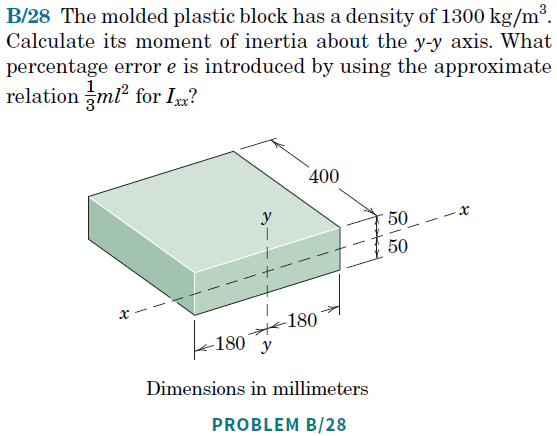

rho = 1300 *u.kg / u.m^3

$$rho = 1300\,\frac{\mathrm{kg}}{m^{3}}$$

l_aprox = 400 * u.mm

$$l\_aprox = 400\,\mathrm{mm}$$

V = 360 * u.mm * 100 * u.mm * 400 * u.mm 

$$V = 14400000\,{\mathrm{mm}}^{3}$$

M = unitConvert(rho * V,"SI")

$$M = \frac{468}{25}\,\mathrm{kg}$$


I_aprox = unitConvert(M*l_aprox^2/3,"SI")

$$I\_aprox = \frac{624}{625}\,\mathrm{kg}\,m^{2}$$

vpa(I_aprox, 3)

$$ans = 0.998\,\mathrm{kg}\,m^{2}$$


a = 400 * u.mm;
b = 360 * u.mm;

I_xx = unitConvert(M*(a^2 + b^2)/12 + M * (b/2)^2,"SI")

$$I\_xx = \frac{16536}{15625}\,\mathrm{kg}\,m^{2}$$


e = vpa((I_xx - I_aprox)/I_xx * 100,3)

$$e = 5.66$$

disp('e ser ud til at være forkert')

e ser ud til at være forkert



I_yy = unitConvert(M*(a^2 + b^2)/12 + M * (a/2)^2,"SI")

$$I\_yy = \frac{18759}{15625}\,\mathrm{kg}\,m^{2}$$

vpa(I_yy, 3)

$$ans = 1.2\,\mathrm{kg}\,m^{2}$$

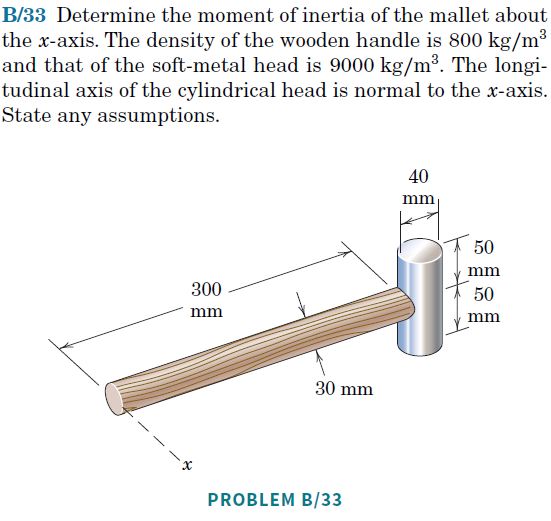

rho_wood = 800*u.kg / u.m^3;
rho_metal = 9000*u.kg / u.m^3;

R_wood = 15 * u.mm;
l_wood = 300 * u.mm;

M_wood = pi*R_wood^2 * l_wood * rho_wood;
vpa(unitConvert(M_wood, 'Si'), 3)

$$ans = 0.17\,\mathrm{kg}$$


I_wood_xx = unitConvert(M_wood*R_wood^2/4 + M_wood*l_wood^2/12 + M_wood*(l_wood/2)^2,"SI"); 
vpa(I_wood_xx,6) %med flytnings bidrag

$$ans = 0.00509892\,\mathrm{kg}\,m^{2}$$


I_wood_xx = unitConvert(M_wood*R_wood^2/4 + M_wood*l_wood^2/3,"SI"); 
vpa(I_wood_xx,6) % med simpel formel

$$ans = 0.00509892\,\mathrm{kg}\,m^{2}$$


R_metal = 20 * u.mm;
l_metal = 100 * u.mm;
M_metal = pi*R_metal^2 * l_metal * rho_metal;
vpa(unitConvert(M_metal, 'Si'), 4)

$$ans = 1.131\,\mathrm{kg}$$


I_metal_xx = unitConvert(M_metal*R_metal^2 / 4 + M_metal * l_metal^2 / 12 + M_metal * (l_wood + R_metal)^2,"SI"); 
vpa(I_metal_xx,3)

$$ans = 0.117\,\mathrm{kg}\,m^{2}$$


% I_metal_xx = unitConvert(M_metal*R_metal^2 / 2 + M_metal * (l_metal/2)^2,"SI"); 
% vpa(I_metal_xx,3)

I_tot_xx = I_wood_xx + I_metal_xx;
vpa(I_tot_xx,3)

$$ans = 0.122\,\mathrm{kg}\,m^{2}$$


%I_tot = 0.1220 kg * m^2